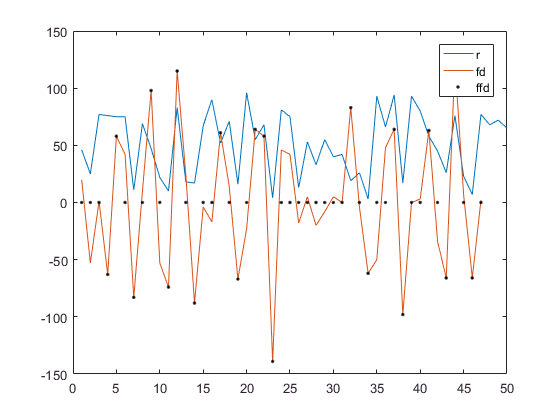

r = unidrnd(100, 1, 50);
[fd, threshold, ffd] = ThreshFiltered(r, 1);
figure;
plot(r); hold on;
plot(fd);hold on;
plot(ffd, 'k.');hold on;
legend({'r', 'fd', 'ffd'})

小结：ThreshFiltered函数验证完成

[up_cross_p, down_cross_p] = CrossPoints(fd, 50)

up_cross_p =      4     5
     8     9
    11    12
    16    17
    20    22
    31    32
    40    41


down_cross_p =      1     2
     6     7
    13    14
    18    19
    33    38


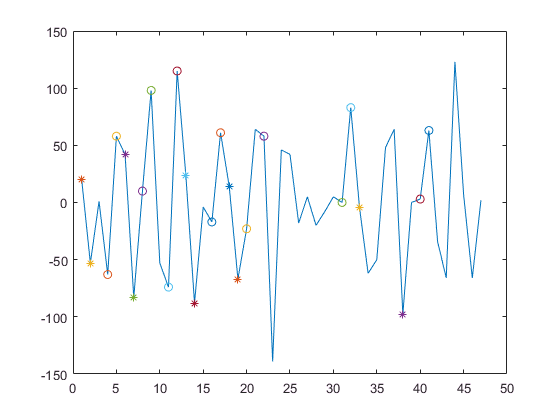

figure;
plot(fd);hold on;
L = size(up_cross_p, 1);
for i=1:L
    scatter(up_cross_p(i, 1), fd(up_cross_p(i, 1)), 'o');hold on;
    scatter(up_cross_p(i, 2), fd(up_cross_p(i, 2)), 'o');hold on;
end
L = size(down_cross_p, 1);
for i=1:L
    scatter(down_cross_p(i, 1), fd(down_cross_p(i, 1)), '*');hold on;
    scatter(down_cross_p(i, 2), fd(down_cross_p(i, 2)), '*');hold on;
end

基于最大值的的尖峰检测算法：针对序列fd展开。

[Y, X] = max(abs(fd));
Y = Y * sign(fd(X))

Y =   -139


X

X =     23


% SpikesX, a matrix with nRx2

NumbInSpikesX(6, [1, 5])

ans =      0


i = 1;
while i<=8
    i
    i=9;
end

i =      1
